# `Mobile camera Calibration`

`This script is to calibrate the mobile camera to be used for monovslam furtherly, it captures N numbers of chess grid images and store inages captured in a folder, then starts calibrating based on those images and same camera parameters object as mobile_camera_params.mat file to be loaded when working with visual slam or needing the parameters for the used camera easily.`

%Initialize the mobile device object
m = mobiledev

m = mobiledev with properties:

                      Device: 'OPPO - CPH1911(ac56)'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
        AvailableMicrophones: {'CPH1911-back' 'CPH1911-bottom'}
          SelectedMicrophone: 'CPH1911-back'

            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 0
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 0
       PositionSensorEnabled: 0
           MicrophoneEnabled: 0
Show all properties

%Create a folder to store the calibration images locally
outputFolder = 'mobile_calibration_images';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

`Below you can identify the numbers of images to be taken and calibrate based on.`

`note: Shutter mode could be manually as well, to do so you could replace 'immediate' below with 'manual'`

cam = camera(m,'back');
numImages = 10;  % Number of images to capture for calibration
for i = 1:numImages
    % Capture a snapshot from the mobile camera
    img = snapshot(cam, 'immediate');
    
    % Convert to grayscale if needed (since it's a mono camera)
    img = rgb2gray(img);
    
    % Save the captured image locally
    filename = fullfile(outputFolder, sprintf('calibration_image_%d.png', i));
    imwrite(img, filename);
    
    % Display the captured image
    figure, imshow(img), title(sprintf('Captured Image %d', i));
    
    pause(5); % Pause before capturing the next image
end

`Adjust squareSize variable t o match chess grid square side used in mm.`

% Load the images from the local folder
imageFiles = imageDatastore(outputFolder);

% Detect the checkerboard corners in the images
[imagePoints, boardSize] = detectCheckerboardPoints(imageFiles.Files);

% Generate world coordinates for the checkerboard corners
squareSize = 17; % Example square size in mm; adjust to match your checkerboard
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Read one of the images to get the image size
I = readimage(imageFiles, 1);
imageSize = [size(I, 1), size(I, 2)];

cameraParams = estimateCameraParameters(imagePoints, worldPoints, 'ImageSize', imageSize)

cameraParams =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [8×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.0925
                 ReprojectionErrors: [70×2×8 double]
                  ReprojectedPoints: [70×2×8 double]

   Calibration Settings
                        NumPatterns: 8
                  DetectedKeypoints: [70×8 logical]
                        WorldPoints: [70×2 double]
                         WorldUnits: 'mm'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


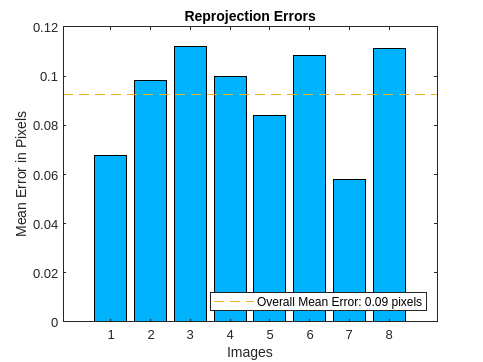

figure;
showReprojectionErrors(cameraParams);
title('Reprojection Errors');

save('mobile_camera_params.mat', 'cameraParams');

figure;
for i = 1:numel(imageFiles.Files)
    I = readimage(imageFiles, i);
    
    % Undistort the image using the calibrated camera parameters
    undistortedImage = undistortImage(I, cameraParams);
    
    % Display original and undistorted images side by side
    subplot(1, 2, 1);
    imshow(I);
    title('Original Image');
    
    subplot(1, 2, 2);
    imshow(undistortedImage);
    title('Undistorted Image');
    
    pause(10); % Pause between images
end